theta_0 = 0;
theta_1 = 40;
a1 = [0 0 0]

a1 =      0     0     0


a2 = [2 2 4]

a2 =      2     2     4



Rz_0 = [cosd(theta_0), -sind(theta_0), 0;
        sind(theta_0), cosd(theta_0), 0;
        0,  0,  1;]

Rz_0 =      1     0     0
     0     1     0
     0     0     1


Rz_1 =  [cosd(theta_1), -sind(theta_1), 0;
        sind(theta_1), cosd(theta_1), 0;
        0,  0,  1;]

Rz_1 =     0.7660   -0.6428         0
    0.6428    0.7660         0
         0         0    1.0000


PXYZ = [Rz_1(1,:) 0; Rz_1(2,:) 0; Rz_1(3,:) 0; 0 0 0 1] * [a2' ; 1] 

PXYZ =     0.2465
    2.8177
    4.0000
    1.0000


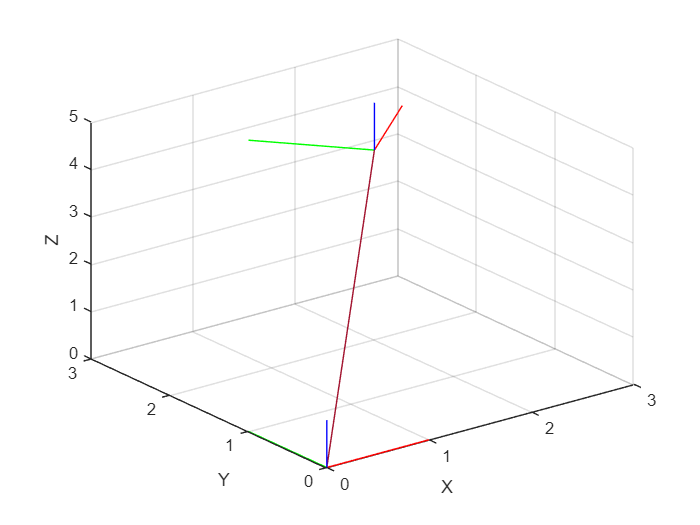

plotTransforms(a1, rotm2quat(Rz_0))
grid on;
hold on;
plotTransforms(a2, rotm2quat(Rz_1))
xlabel('X')
ylabel('Y')
zlabel('Z')
plot3([a1(1) a2(1)], [a1(2) a2(2)], [a1(3) a2(3)] )